% [training_data, testing_data]=Split_data(data);

training_data_p=data(tr_lm.trainInd,[1:5,14]);

training_data_nu=data(tr_lm.trainInd,[1:5,15]);

testing_data_p=data(tr_lm.valInd,[1:5,14]);

testing_data_nu=data(tr_lm.valInd,[1:5,15]);

**Creating Initial FIS for ANFIS Training**

name_anfis={'trapmf','gbellmf','trimf','gaussmf','gauss2mf'};
T_nu=array2table(zeros(1,5),"VariableNames",{'mae','mse','rmse','Rsq','mape'});
T_p=array2table(zeros(1,5),"VariableNames",{'mae','mse','rmse','Rsq','mape'});

for i=1:length(name_anfis)   
    genOpt = genfisOptions('GridPartition');
    genOpt.NumMembershipFunctions =3;
    genOpt.InputMembershipFunctionType = name_anfis{i};
    genOpt.OutputMembershipFunctionType='constant';
    inFIS = genfis(training_data_nu(:,1:5),training_data_nu(:,6),genOpt);

**Configure anfis Training option**

    opt = anfisOptions('InitialFIS',inFIS,'EpochNumber',300);
    opt.DisplayANFISInformation = 0;
    opt.DisplayErrorValues = 0;
    opt.DisplayStepSize = 0;
    opt.DisplayFinalResults = 0;

    anfis_nu = anfis([training_data_nu(:,1:5) training_data_nu(:,6)],opt);

**Nusselt Number Ratio**

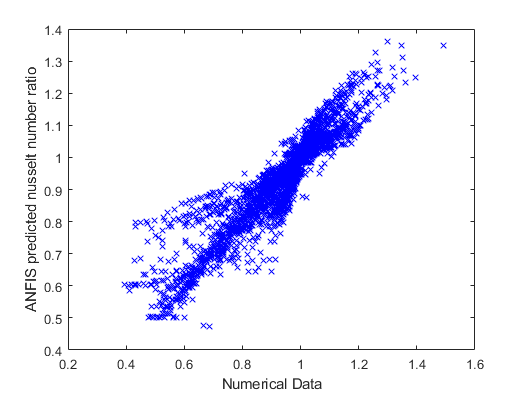

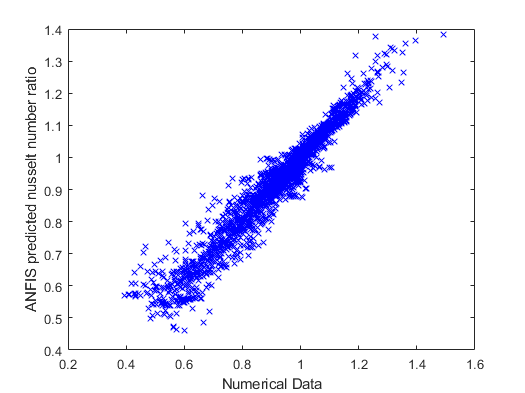

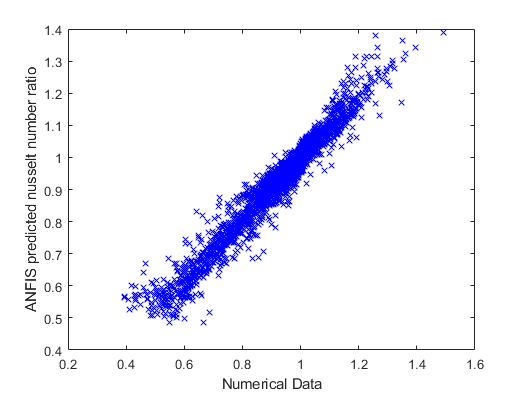

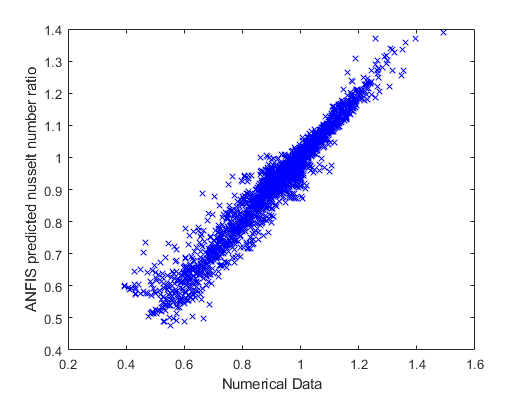

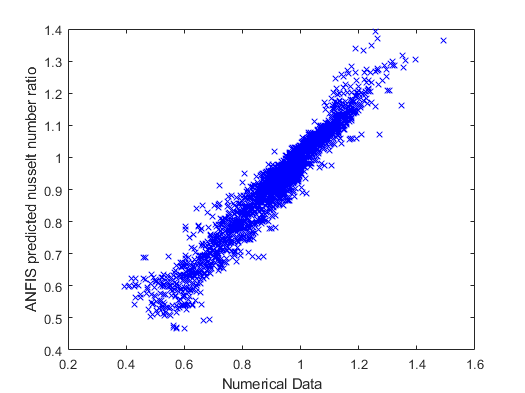

    input_fuzzy=testing_data_nu(:,1:5);
    anfisoutput=evalfis(anfis_nu,input_fuzzy);
    anfisoutput_nu{i}=anfisoutput;
    figure()
    plot(testing_data_nu(:,6),anfisoutput,'x','color','b')
    xlabel('Numerical Data')
    ylabel('ANFIS predicted nusselt number ratio')
    name_plot_anfis_nu=sprintf('D:/Matlab Drive/Research/Fuzzy/Figure/Nu Ratio, MF %s.bmp',name_anfis{i});
    saveas(gca,name_plot_anfis_nu)

    % legend('Training Data','ANFIS Output','Location','NorthWest')

    T_nu_new=rMetrics(testing_data_nu(:,6),anfisoutput);
    T_nu=[T_nu;T_nu_new];

**Pressure Ratio**

    anfis_p=anfis([training_data_p(:,1:5) training_data_p(:,6)],opt);

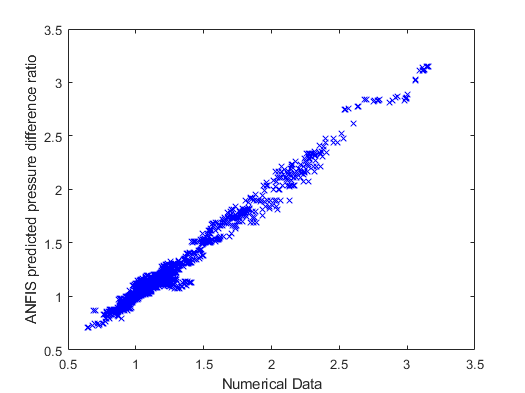

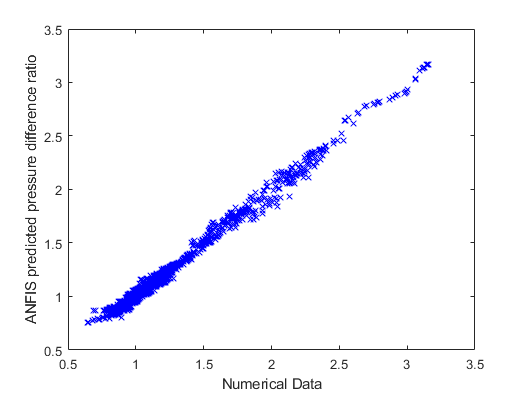

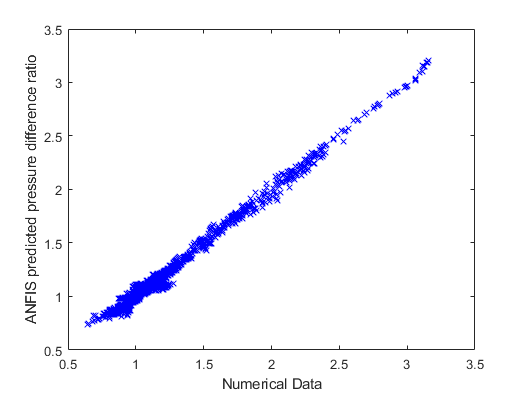

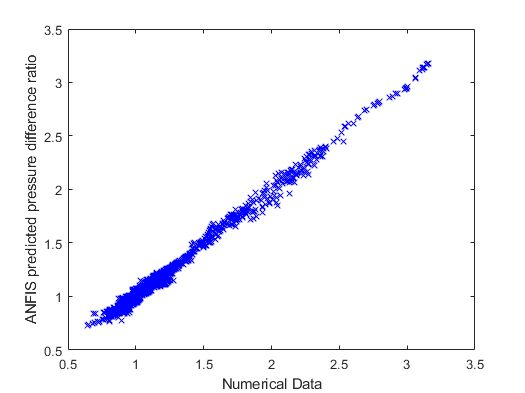

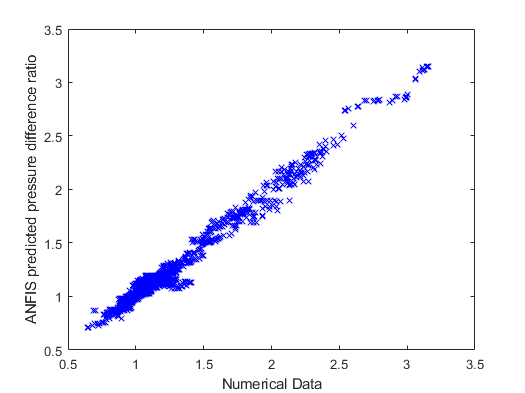

    input_fuzzy=testing_data_p(:,1:5);
    anfisoutput=evalfis(anfis_p,input_fuzzy);
    anfisoutput_p{i}=anfisoutput;
    figure()
    plot(testing_data_p(:,6),anfisoutput,'x','color','b')
    xlabel('Numerical Data')
    ylabel('ANFIS predicted pressure difference ratio')
    name_plot_anfis_p=sprintf('D:/Matlab Drive/Research/Fuzzy/Figure/P Ratio, MF %s.bmp',name_anfis{i});
    saveas(gca,name_plot_anfis_p)

    T_p_new=rMetrics(testing_data_p(:,6),anfisoutput);
    T_p=[T_p;T_p_new];
end

T_nu;
T_p;
rownames_anfis={'trapmf';'gbellmf';'trimf';'gaussmf';'gauss2mf'};
T_nu_disp=cat(2,rownames_anfis,T_nu(2:6,:))

T_nu_disp = 5×6 table
        Var1          mae          mse         rmse        Rsq        mape  
    ____________    ________    _________    ________    _______    ________

    {'trapmf'  }    0.036445    0.0031836    0.056423    0.86168    0.044042
    {'gbellmf' }    0.023801    0.0013703    0.037017    0.94046    0.029599
    {'trimf'   }    0.023334    0.0011228    0.033508    0.95122    0.027748
    {'gaussmf' }    0.023328    0.0013519    0.036769    0.94126    0.029005
    {'gauss2mf'}     0.02758    0.0015561    0.039447    0.93239    0.033177


T_p_disp=cat(2,rownames_anfis,T_p(2:6,:))

T_p_disp = 5×6 table
        Var1          mae          mse          rmse        Rsq        mape  
    ____________    ________    __________    ________    _______    ________

    {'trapmf'  }    0.027932     0.0019481    0.044138    0.98475    0.023487
    {'gbellmf' }     0.02156    0.00097172    0.031172    0.99239    0.018932
    {'trimf'   }     0.02112    0.00096665    0.031091    0.99243    0.018874
    {'gaussmf' }    0.021484    0.00094144    0.030683    0.99263    0.019182
    {'gauss2mf'}    0.027755     0.0019371    0.044012    0.98484    0.023394


writetable(T_nu_disp,"D:/Matlab Drive/Research/Fuzzy/Table/Performence.xlsx",'Sheet','Nu ratio');
writetable(T_p_disp,"D:/Matlab Drive/Research/Fuzzy/Table/Performence.xlsx",'Sheet','Pressure ratio');